input = imread('hw2_files/Q3/1/1.png');
[row,col,~] = size(input)

row = 332

col = 332

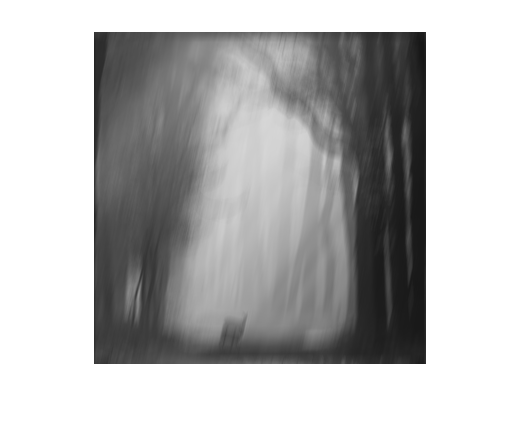

YCBCR = rgb2ycbcr(input);
imshow(YCBCR(:,:,1))

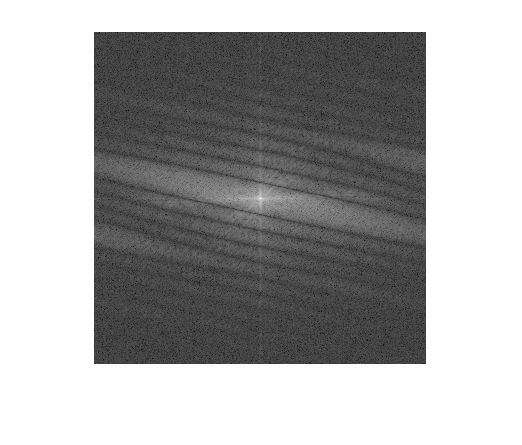

fshift = fftshift(fft2(YCBCR(:,:,1)));
magintude = 15*log(abs(fshift));
imshow(uint8(magintude))


T = 1-imbinarize(uint8(magintude),"adaptive","Sensitivity",0.65)

T =      0     0     1     0     1     1     0     0     0     0     0     1     0     0     0     1     0     1     0     0     0     1     1     1     0     0     0     0     1     1     0     1     0     0     0     0     1     0     0     0     0     1     1     0     1     0     0     1     0     1
     1     1     1     1     1     1     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     1     0     0     1     0     1     0     1
     0     1     0     0     1     0     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     1     0     0     0     1     0     0     0     0     0     0     0
     1     0     0     0     0     0     1     0     1     0     0     0     1     0     1   

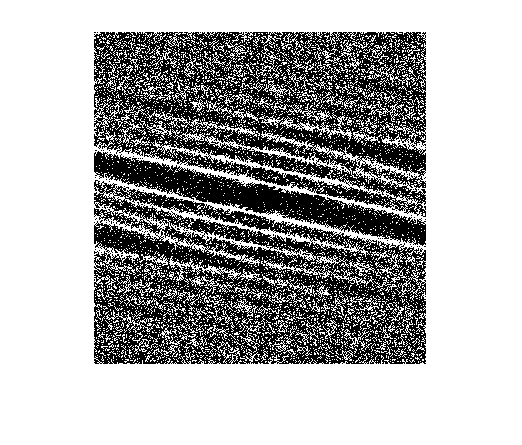

imshow(T)


kernel = ones([3,3],"uint8")

kernel = 3×3 uint8 矩阵
   1   1   1
   1   1   1
   1   1   1


morph = imopen(T,kernel)

morph =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

kernel = ones([1,9],"uint8")

kernel = 1×9 uint8 行向量
   1   1   1   1   1   1   1   1   1


morph = imclose(morph,kernel)

morph =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

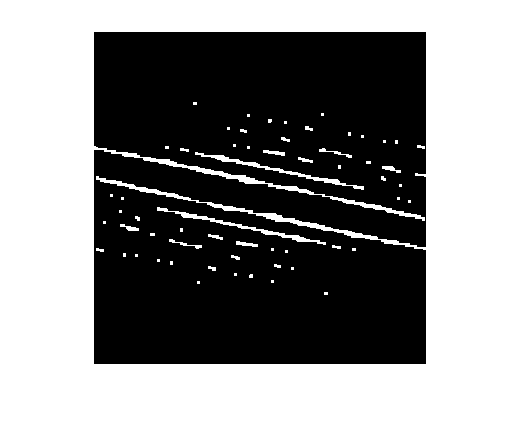

imshow(morph)


BW1 = edge(morph,'Canny');
imshow(morph)


[H,T,R] = hough(BW1);
P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
lines = houghlines(BW1,T,R,P,'FillGap',5,'MinLength',7);
figure, imshow(uint8(magintude)), hold on
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end
theta = lines(1).theta;

rotated = imrotate(uint8(magintude),theta)

rotated = 394×394 uint8 矩阵
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

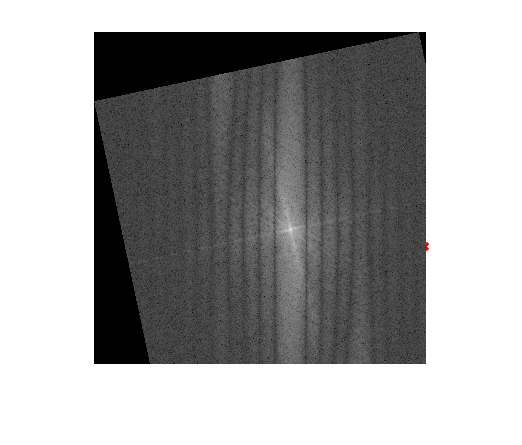

imshow(rotated)


proj = sum(rotated,1)

proj =          118         462         677        1095        1458        1633        2029        2366        2802        3098        3379        3657        3861        4301        4677        4943        5322        5582        5883        6231        6431        6909        7226        7265        7693        8226        8397        8751        9189        9315        9835        9889       10563       11022       10936       11420       11891       12039       12345       12742       13100       13333       13715       13716       14321       14898       14861       15251       15815       16249


xaxis = 1: length(proj)

xaxis =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


[val,maxIndex] = max(proj)

val = 41453

maxIndex = 197

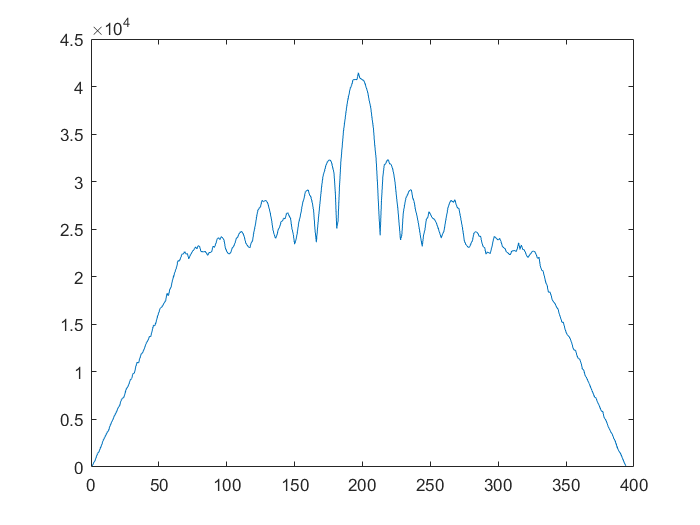

figure
plot(xaxis,proj)

for i = 1:100
    if proj(maxIndex-i) - proj(maxIndex-i-1) < -1000
        index_1 = i;
        break
    end
end
for i = 1:100
    if proj(maxIndex+i) - proj(maxIndex+i+1) < -1000
        index_2 = i;
        break
    end
end

if abs(index_1 - index_2) >= 5
    index_1 = max([index_1, index_2])
    index_2 = max([index_1, index_2])
end

L = 2 * row / (index_1 + index_2)

L = 20.7500

H = fspecial('motion',L,theta)

H =          0    0.0316         0         0         0         0         0
         0    0.0441    0.0052         0         0         0         0
         0    0.0341    0.0152         0         0         0         0
         0    0.0241    0.0252         0         0         0         0
         0    0.0140    0.0352         0         0         0         0
         0    0.0040    0.0452         0         0         0         0
         0         0    0.0411    0.0081         0         0         0
         0         0    0.0311    0.0181         0         0         0
         0         0    0.0211    0.0282         0         0         0
         0         0    0.0111    0.0382         0         0         0


错误使用  / 
矩阵维度必须一致。